## Super fast introduction to CasADi

### Simple optimization

This very brief example shows how to use casadi framework to solve a very simple optimization problem in which we just want to minimize a function

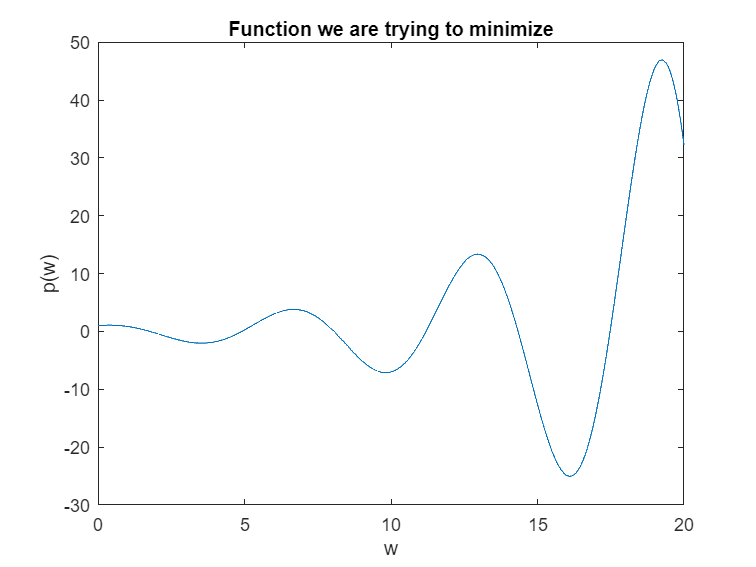

clc
clear all
close all
import casadi.*

opti = Opti();
w = opti.variable(1); % Define the optimization variable as a scalar
p = 0.2*exp(0.2*w).*(sin(w)+5*cos(w)); % Just a function we want to minimize

% Show the function
wplot = 0:0.001:20;
p_plot = 0.2*exp(0.2.*wplot).*(sin(wplot)+5.*cos(wplot));
plot(wplot, p_plot)
title("Function we are trying to minimize")
xlabel("w")
ylabel("p(w)")

Here we setup the optimization problem

opti.minimize(p); % Cost function
opti.subject_to(w>=0) % Contraint
opti.solver('ipopt'); % Solver used to actually solve the optimization
opti.set_initial(w, 5); % Set initial value. Note that this may affect the result (try to set it at 15)
sol = opti.solve() % Solve

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        3
Number of nonzeros in Lagrangian Hessian.............:        1

Total number of variables............................:        1
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        3
        inequality constraints with only lower bounds:        3
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 2

sol = Opti {
  instance #2144
  #variables: 1 (nx = 1)
  #parameters: 0 (np = 0)
  #constraints: 3 (ng = 3)
  CasADi solver allocated.
  CasADi solver was called: Solve_Succeeded
}

Now display the solution

wstar = sol.value(w) % Parameters that minimize the cost

wstar = 3.5364

pstar = sol.value(p) % Value of the cost function at wstar

pstar = -2.0285

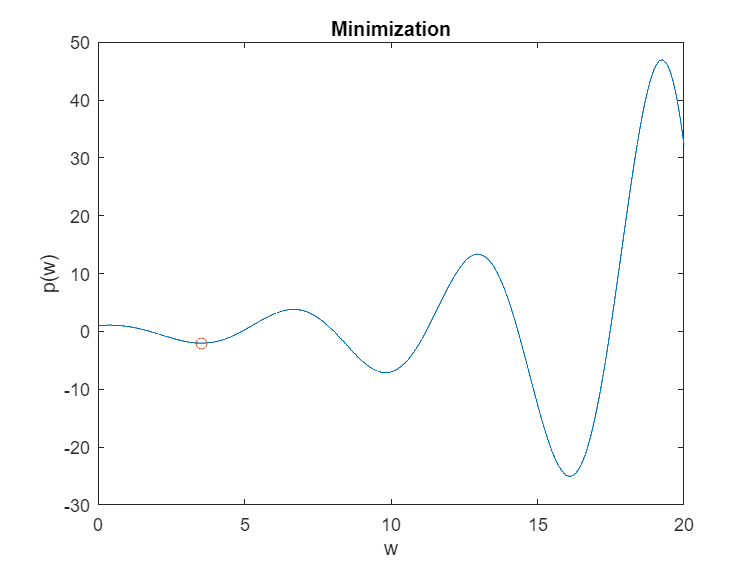


figure
plot(wplot, p_plot)
hold on 
scatter(wstar, pstar)
title("Minimization")
xlabel("w")
ylabel("p(w)")

### Simulate the forced response of a damped oscillator

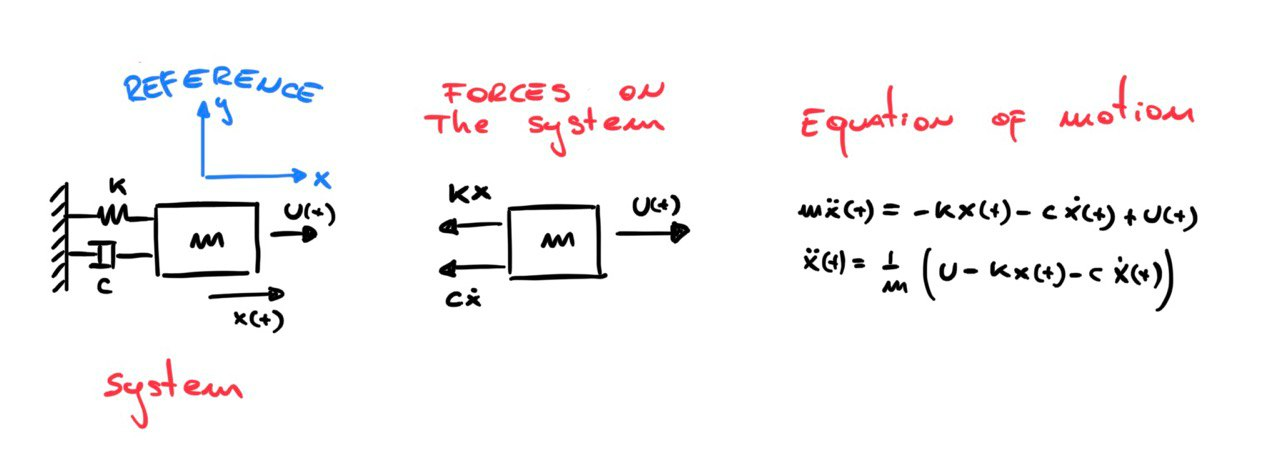

Here we do a bit of practice using the casadi symbols. It will be then used as a basis for a more interesting optimization.

The system under analysis is shown in figure. The equation of motion is written using CasADi symbols. Note that being this a linear dynamical system, the differential equation can be solved using Laplace Transform. Here we do not do so just to show how casadi can be used.

import casadi.*
m=1; k=5; c=0.7; dt=0.01; % Parameters of the oscillator system

x1 = SX.sym('x1') % Define a variable x1 as a symbol (position)

x1 = x1

x2 = SX.sym('x2') % Define a variable x2 as a symbol (velocity)

x2 = x2

U = SX.sym('F') % Define a variable F as a symbol (force)

U = F

X = [x1;x2]; % state vector
x0 = [1; 0]

x0 =      1
     0


The dynamics is linear, so Laplace Transform can be used. This is just an example to show the CasADi tools

ode = [x2; (-k*x1 - c*x2 + U)/m] % dynamics of the system

ode = [x2, (((-5*x1)-(0.7*x2))+F)]

Now we need a mapping from the state and control to the future state of the system

% Now we can create a CasADi function, which basically 
% just put the arguments: X and U into the output: ode
f = Function('f', {X, U}, {ode}) % This could have been the kinematics model of a robot

f = f:(i0[2],i1)->(o0[2]) SXFunction

f([0; 2], 0)

ans = [2, -1.4]

Now we can simulate the motion of the system. To do so we need to integrate the dynamics.

There are different ways to do so. In this case we will use a simple explicit Euler Integration, but CasADi also implements integration function with many options

% If we want to get the state at the next timestep we have to integrate
x_new = x0 + f(x0, 0)*dt

x_new = [1, -0.05]

Now simulate  the system for 10 seconds

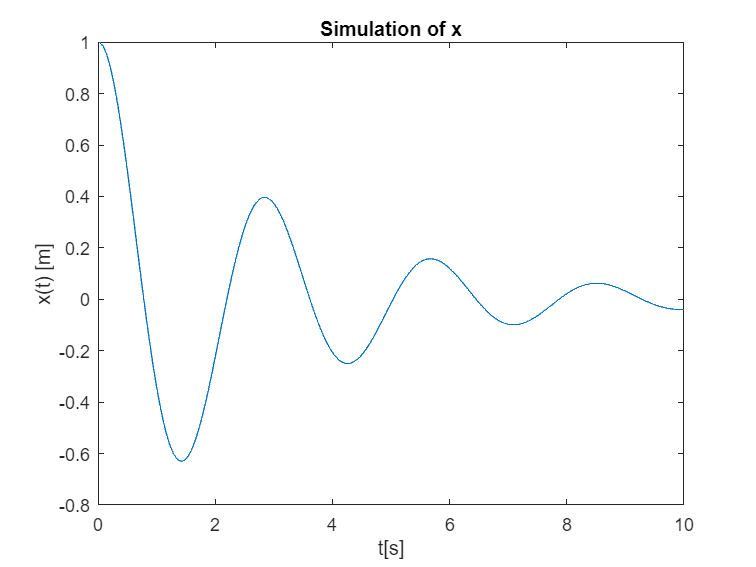

T = 10; %5 seconds of simulation
N = round(T/dt,0);
t = linspace(0, T, N+1);
x_int = cat(2, x0, zeros(2, N));
for i=1:N
    x_int(:, i+1) = x_int(:, i) + full(f(x_int(:, i), 0)*dt);
end

figure
plot(t, x_int(1, :))
title("Simulation of x")
xlabel("t[s]")
ylabel("x(t) [m]")

### Optimal control for the damped oscillator

Now some more interesting stuff. 

We move the mass away from its equilibrium (i.e. we are stretching the spring) and we ask: "How should an external force behave in order to stabilize (bring the system to zero position and velocity) the system as fast as possible? 

opti = Opti()

opti = Opti {
  instance #2143
  #variables: 0 (nx = 0)
  #parameters: 0 (np = 0)
  #constraints: 0 (ng = 0)
  CasADi solver needs updating.
}

xs = opti.variable(2, N+1); % state
us = opti.variable(1, N); % control

wx = 10; wu = 0.1; % weights of the cost function
cost = 0;
opti.subject_to(xs(:, 1) == x0); % initial condition is to start at some x0 displacement
for i=1:N % this is a sum over all the timesteps
    cost = cost + ( wx*sumsqr(xs(1, i)) + wu*sumsqr(us(i)))*dt; % Cost function is zero only at equilibrium
    opti.subject_to(xs(:, i+1) == xs(:, i) + f(xs(:, i), us(i))*dt); % We have to impose continuity constraints. (basically dynamics)
end
opti.minimize(cost) % Minimize the cost
opti.solver('ipopt')
opti.solve()

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     7002
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     2000

Total number of variables............................:     3002
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     2002
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

ans = Opti {
  instance #2143
  #variables: 2 (nx = 3002)
  #parameters: 0 (np = 0)
  #constraints: 1001 (ng = 2002)
  CasADi solver allocated.
  CasADi solver was called: Solve_Succeeded
}

Now that the optimization has been solved, let's check the results

xsol = opti.value(xs)

xsol =     1.0000    1.0000    0.9989    0.9967    0.9935    0.9894    0.9843    0.9783    0.9714    0.9637    0.9552    0.9459    0.9359    0.9253    0.9140    0.9021    0.8896    0.8766    0.8631    0.8490    0.8346    0.8197    0.8045    0.7889    0.7730    0.7568    0.7403    0.7236    0.7067    0.6896    0.6724    0.6550    0.6375    0.6199    0.6023    0.5846    0.5669    0.5491    0.5314    0.5138    0.4962    0.4787    0.4612    0.4439    0.4267    0.4096    0.3927    0.3759    0.3593    0.3429
         0   -0.1102   -0.2164   -0.3186   -0.4168   -0.5112   -0.6016   -0.6882   -0.7710   -0.8501   -0.9254   -0.9971   -1.0651   -1.1296   -1.1905   -1.2481   -1.3022   -1.3529   -1.4004   -1.4447   -1.4858   -1.5239   -1.5589   -1.5910   -1.6201   -1.6465   -1.6702   -1.6911   -1.7095   -1.7253   -1.7387   -1.7497   -1.7584   -1.7648   -1.7691   -1.7712   -1.7714   -1.7696   -1.7659   -1.7603   -1.7531   -1.7441   -1.7336   -1.7215   -1.7079   -1.6930   -1.6767   -1.6591   -1.6403  

usol = opti.value(us)

usol =    -6.0178   -5.6951   -5.3775   -5.0652   -4.7583   -4.4569   -4.1613   -3.8714   -3.5875   -3.3096   -3.0378   -2.7723   -2.5130   -2.2601   -2.0137   -1.7736   -1.5401   -1.3130   -1.0926   -0.8786   -0.6713   -0.4704   -0.2762   -0.0884    0.0928    0.2676    0.4359    0.5978    0.7533    0.9026    1.0456    1.1824    1.3131    1.4378    1.5565    1.6693    1.7763    1.8775    1.9732    2.0633    2.1479    2.2272    2.3013    2.3702    2.4341    2.4931    2.5472    2.5966    2.6415    2.6818


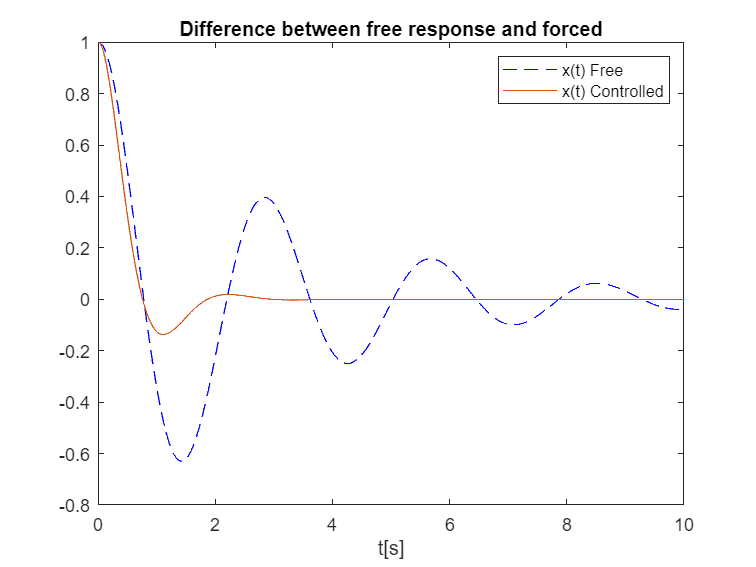

figure
plot(t, x_int(1, :), 'b--')
title("Difference between free response and forced")
hold on
plot(t, xsol(1, :))
xlabel("t[s]")
legend("x(t) Free", "x(t) Controlled")

This is the control action that drives the system in that way

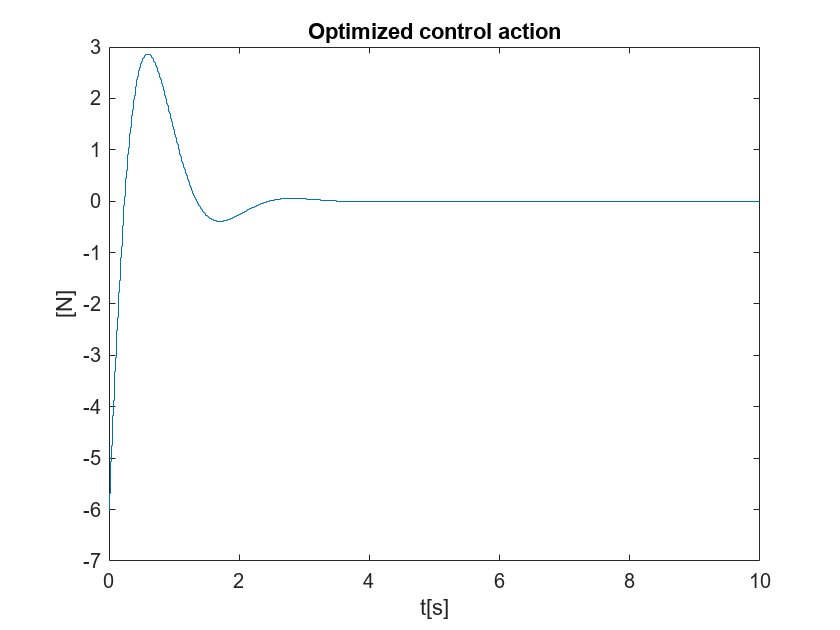

figure
stairs(t(1:end-1), usol)
title("Optimized control action")
xlabel("t[s]")
ylabel("[N]")